# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

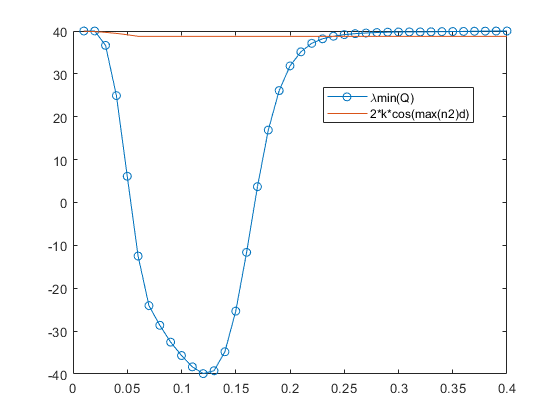

clear all ; close all
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global D h k;

down_sample_amount = 8;

d = 5; % delay amount \delta

% Circle
D = .8; k = 20; h = 0.01;
position = importdata("position_Array.mat");


l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
     
statea(:,1) =[position(1,1); position(2,1); pi/6];

state(:,1) =[position(1,1); position(2,1); pi/6];

xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1);  
theta_hat(1) = state(3,1);

xba(1) = state(1,1) + D*cos(state(3,1));
yba(1) = state(2,1) + D*sin(state(3,1));
thetaa(1) = state(3,1); 


  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;
  
  xVelocitya = (position(1,t+1) - position(1,t))/h;
  yVelocitya = (position(2,t+1) - position(2,t))/h;

for t = 1 : T
    n1(t) = 3*randn(1);
    n2(t) = 3*randn(1);

    % x= current state
    xa = [xba(t); yba(t); thetaa(t)];
    x = [xb(t); yb(t); theta_hat(t); theta(t)];
    
    % controller returns the desired velocities
    [va, wa] = controller(xa, xVelocitya(t), yVelocitya(t),position(:,t));
    [v(t), w(t)] = controller(x(1:3,1), xVelocity(t), yVelocity(t),position(:,t));
    % use the dynamics with desired velocities to generate the velocities
    dot_xa = dynamics(xa,va,wa,n1(t),n2(t));
    dot_x(:,t) = dynamics([x(1); x(2); x(4)],v(t),w(t),n1(t),n2(t));
    
     linear_vela(t) = va+n1(t);
     angular_vela(t) = wa+n2(t);
     
     linear_vel(t) = v(t)+n1(t);
     angular_vel(t) = w(t)+n2(t);
     
    % centroid dynamics
    %actual
    statea(:,t+1) = statea(:,t) + h* [(va+n1(t))*cos(statea(3,t)); (va+n1(t))*sin(statea(3,t)); wa+n2(t)];  
    %noise
    state(:,t+1) = state(:,t) + h* [(v(t)+n1(t))*cos(state(3,t)); (v(t)+n1(t))*sin(state(3,t)); w(t)+n2(t)];
    
   

    % integrate the position to get the new position
    
    %actual
    xba(t+1) = xba(t) + dot_xa(1)*h;
    yba(t+1) = yba(t) + dot_xa(2)*h;
    thetaa(t+1) = thetaa(t) + dot_xa(3)*h;
    
    %estimated
    xb(t+1) = xb(t) + dot_x(1,t)*h;
    yb(t+1) = yb(t) + dot_x(2,t)*h;
    theta(t+1) = theta(t) + dot_x(3,t)*h;
    
    if t-d >= 1
        i=0;
    for l = t-d:t
        i = i+1;
        w_delay(i) = w(l);
        
        
    end
         theta_hat(t+1) = atan2((state(2,t+1-d)-state(2,t-d))/(v(t-d)+n1(t-d)), ...
             (state(1,t+1-d)-state(1,t-d))/(v(t-d)+n1(t-d))) + sum(w_delay)*h;
    else
        i=0;
        for l = 1:t
        i = i+1;
        w_delay(i) = w(l);

        end
        theta_hat(t+1) = theta(1)+pi+ sum(w_delay)*h;
    end

end
z_dot = [0];
for i = 2:length(theta)
z_dot = [position(1,i)-position(1,i-1); 
            position(2,i)-position(2,i-1)];
z_dot_norm(i) = norm(z_dot);
end

for i = 1:length(theta)
    Q(i) = k*2*cos(thetaa(i)-theta(i));
    error_bound(i) = 2*(z_dot_norm(i))^2/Q(i);
end
 
error = [position(1,:) - xb; position(2,:) - yb];
for i = 1:length(error)
    norm_error(i) = norm(error(i));
end

for i = 1:length(theta)
B = [cos(thetaa(i)-theta(i)) -sin(thetaa(i)-theta(i));
      sin(thetaa(i)-theta(i)) cos(thetaa(i)-theta(i))];
Q_B(i) = min(eig(k*(B'+B)));
end 

for i = 1:length(Q)
   if i <= d
    m(i) = 2*k*cos(max(n2)*i*h);
   else
    m(i) = 2*k*cos(max(n2)*(d+1)*h);
   end
end

figure
plot([1:length(xb(1,:))]*h, Q, 'o-')
hold on
plot([1:length(xb(1,:))]*h, m)
legend(['\lambda','min(Q)'], '2*k*cos(max(n2)d)','location','best')
hold off

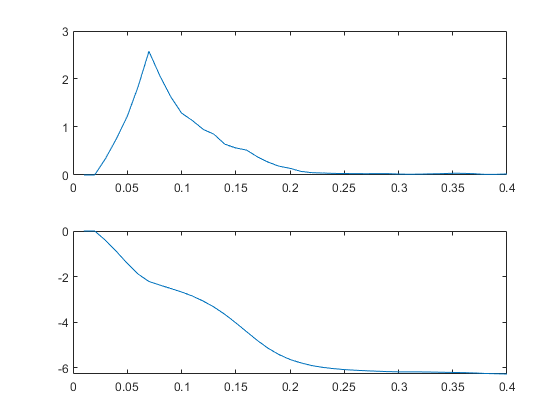

% 
% figure
% plot([1:length(xb(1,:))]*h, norm_error)
% hold on
% plot([1:length(xb(1,:))]*h, error_bound)
% % title('Bounded e: \delta = 3, n1,n2 = ||5||')
% legend('||e||', 'Steady state limit')
% hold off
    
for i =1 : length(xb(1,:))
   position_distance(i) = norm( [xb(1,i), yb(1,i)] - [xba(1,i), yba(1,i)] ); 
   angular_distance(i) = theta(i) - thetaa(i); 
end
subplot(2,1,1)
plot([1:length(xb(1,:))]*h, position_distance);
subplot(2,1,2)
plot([1:length(xb(1,:))]*h, angular_distance);

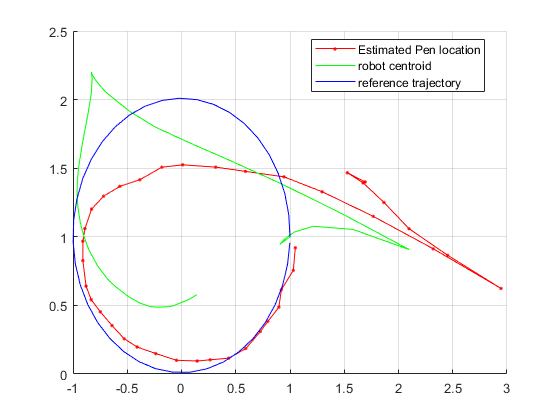



  max_error(1) = max(abs(n2(1:1+d)));
    i = 1;
    for l = 1+d:d:T-d
    i = i+1;
      max_error(i) = d*max(abs(n2(l:l+d-1)));
    end
% figure 
% plot([0:length(theta)-1]*h,mod(abs(thetaa-theta),2*pi))
% hold on
% stairs([0:d:length(max_error)-1]*h, max_error)
% title('|\theta_{error}|')
% hold off

% figure
% hold on
% stairs([0:d:T-d-1]*h, max_error)
% 
% title('\delta = 5, t-d<=S<=t')
% ylabel('\delta*max|n2(s)|')
% xlabel('t')
% hold off

figure
% plot(xba, yba, '.-')
hold on;
plot(xb, yb, '.-','color','r')
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:),'color','b');
grid on;
legend('Estimated Pen location', 'robot centroid', 'reference trajectory', "location", 'best')
hold off

% 
% figure
% plot([1:size(linear_vel,2)]*h, linear_vel); hold on
% plot([1:size(angular_vel,2)]*h, angular_vel);
% legend('linear velocity (v)', 'angular velocity (w)')

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k
 

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];

v_feedback = [xVelocity; yVelocity] - k*( x(1:2,1)- [position(1); position(2)]);

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w,n1,n2)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v+n1; w+n2];

end
